clearvars;
addpath('ego');
addpath('kwave');

# Image source method and kwave for room acoustics simulation

In the following we will simulate the propagation from an acoustic source to a receiver in a 2 dimensional rectangle room using the image source method and the matlab toolbox kwave. We will use the kwave implementation as a reference to analyse wether the image source method is accurate and how the image order affects that accuracy.

### Parameter initializazion

frequency = 0.25e6; % Signal frequency in Hz
dimension = 2^5; % Computational grid x and y dimensions
spacing = 50e-3/dimension; % Spacing between each point of the grid
c = 343; % speed of sound
alpha = 0;
p_source = [0,0]; % Source coordinates
p_receiver = [-8,8]; % Receiver coordinates

## kwave method

[t,scale,kwave_in_p, kwave_out_p] = point_source(p_source, p_receiver, frequency, dimension, spacing);

Filtering input signal...
  maximum frequency supported by kgrid: 109.76kHz (2 PPW)
  filter cutoff frequency: 73.1733kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 03-Nov-2021 14:06:40
  reference sound speed: 343m/s


Error using kspaceFirstOrder_inputChecking (line 1382)
The size of the PML must be smaller than the size of the grid.

Error in kspaceFirstOrder2D (line 537)
kspaceFirstOrder_inputChecking;

Error in 

## Image source method

----------------------------------------
Plane and point coordinates for GeoGebra
----------------------------------------
Plane((0,0,0),(0,1,0),(0,0,1))
Plane((0,0,0),(0,0,1),(1,0,0))
Plane((128,0,0),(128,1,0),(128,0,1))
Plane((0,128,0),(1,128,0),(0,128,1))
(64,64,0)
(-64,64,0)
(64,-64,0)
(192,64,0)
(64,192,0)
(-64,-64,0)
(320,64,0)
(-64,192,0)
(192,-64,0)
(64,320,0)
(-192,64,0)
(192,192,0)
(64,-192,0)
----------------------------------------


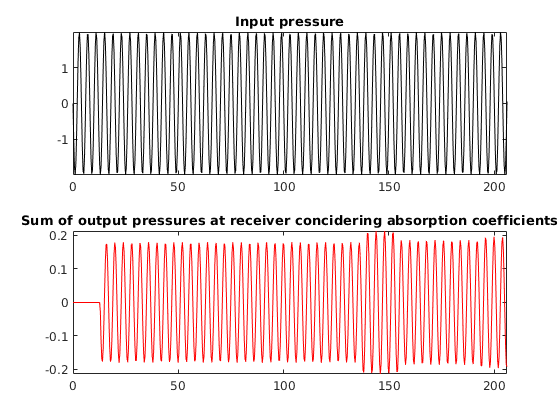

image_order = 2;
alpha = [0 0 0 0];
[tot_output_pressure] = image_source_pressure_wave([p_source 0],[p_receiver 0],dimension,dimension,dimension,t,scale,spacing,c,frequency,image_order,alpha);